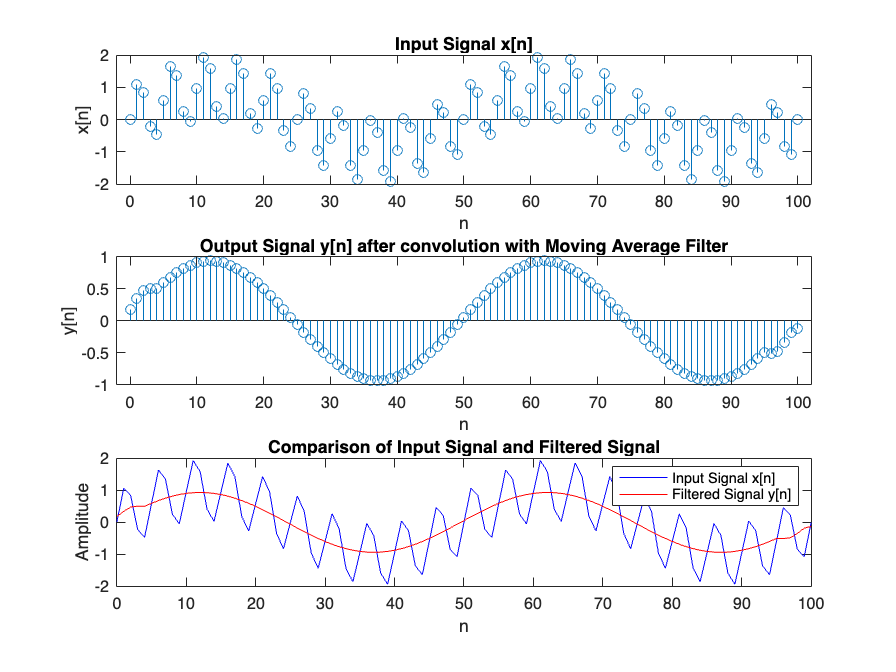

% convolving with a moving average filter
nx = [0:100];
x = sin(2*pi*nx/50) + sin(20*pi*nx/50);

figure;
subplot(3,1,1)
stem(nx, x);
title('Input Signal x[n]');
xlabel('n');
ylabel('x[n]');

h=0.1*ones(1,10);
nh = [0:9];


% Convolve x with the filter h
y = conv(x, h, 'same');  % 'same' keeps the output length the same as input
subplot(3,1,2)
stem(nx, y);
title('Output Signal y[n] after convolution with Moving Average Filter');
xlabel('n');
ylabel('y[n]');


% Using the plot function
subplot(3,1,3)
plot(nx, x, 'b', 'DisplayName', 'Input Signal x[n]');
hold on;
plot(nx, y, 'r', 'DisplayName', 'Filtered Signal y[n]');
legend;
title('Comparison of Input Signal and Filtered Signal');
xlabel('n');
ylabel('Amplitude');


% this is the implementation of a low pass filter, which filters out higher
% frequency (the second sine term of x), essentially smoothing the signal overall.